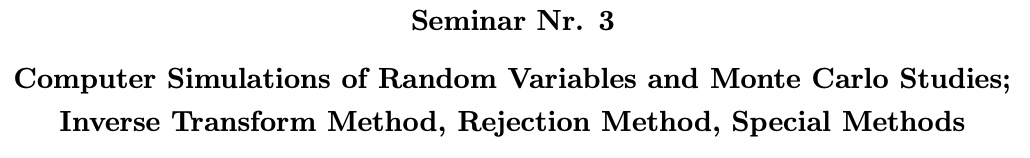

clear all;
generator = input('Generator (1-7): ');

function N=computeSimulationsCount()
    err = input('error = '); % maximum error
    alpha = input('alpha (level of significance) = '); % significance level

    % Compute MC size to ensure that the error is < err, with confidence level 1 - alpha
    N = ceil(0.25 * (norminv(alpha / 2, 0, 1) / err)^2); 
    fprintf('Nr. of simulations N = %d', N);
end

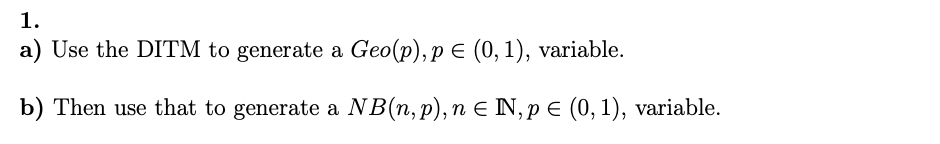

% a) Geo DITM
if generator==1
    p = input('p (in (0,1)) = ');
    
    N = computeSimulationsCount();
    X = ceil(log(1 - rand(1, N)) / log(1 - p) - 1) % Geo variables

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X == 2))
    fprintf('true probab. P(X = 2) = %1.5f\n', geopdf(2, p))
    fprintf('error = %e\n\n', abs(geopdf(2, p) - mean(X == 2)))
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X <= 2))
    fprintf('true probab. P(X <= 2) = %1.5f\n', geocdf(2, p))
    fprintf('error = %e\n\n', abs(geocdf(2, p) - mean(X <= 2)))
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2))
    fprintf('true probab. P(X < 2) = %1.5f\n', geocdf(1, p))
    fprintf('error = %e\n\n', abs(geocdf(1, p) - mean(X < 2)))
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X))
    fprintf('true mean E(X) = %5.5f\n', (1 - p)/p)
    fprintf('error = %e\n\n', abs((1 - p)/p - mean(X)))
end
% b) NBin DTIM
if generator==2
    p = input('p (in (0,1)) = ');
    n = input('n (positive integer) = ');

    N = computeSimulationsCount();
    X = zeros(1, N);
    for i = 1:N
        Y = ceil(log(1 - rand(n, 1))/log(1 - p) - 1); % Geo variables
        X(i) = sum(Y);
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X == 2))
    fprintf('true probab. P(X = 2) = %1.5f\n', nbinpdf(2, n, p))
    fprintf('error = %e\n\n', abs(nbinpdf(2, n, p) - mean(X == 2)))
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X <= 2))
    fprintf('true probab. P(X <= 2) = %1.5f\n', nbincdf(2, n, p))
    fprintf('error = %e\n\n', abs(nbincdf(2, n, p) - mean(X <= 2)))
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2))
    fprintf('true probab. P(X < 2) = %1.5f\n', nbincdf(1, n, p))
    fprintf('error = %e\n\n', abs(nbincdf(1, n, p) - mean(X < 2)))
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X))
    fprintf('true mean E(X) = %5.5f\n', n*(1 - p)/p)
    fprintf('error = %e\n\n', abs(n*(1 - p)/p - mean(X)))    
end

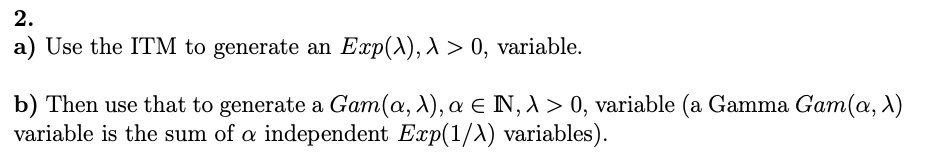

% a) Exp ITM
if generator==3
    lambda = input('lambda ( > 0) = ');

    N = computeSimulationsCount();
    X = -1 / lambda * log(rand(1, N))

    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X <= 2))
    fprintf('true probab. P(X <= 2) = %1.5f\n', expcdf(2, 1/lambda))
    fprintf('error = %e\n\n', abs(expcdf(2, 1/lambda) - mean(X <= 2)))
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2))
    fprintf('true probab. P(X < 2) = %1.5f\n', expcdf(2, 1/lambda))
    fprintf('error = %e\n\n', abs(expcdf(2, 1/lambda) - mean(X < 2)))
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X))
    fprintf('true mean E(X) = %5.5f\n', 1/lambda)
    fprintf('error = %e\n\n', abs(1/lambda - mean(X)))
end
% b) Gam ITM
if generator==4
    a = input('a (positive integer) = ');
    lambda = input('lambda ( > 0) = ');

    N = computeSimulationsCount();
    X = zeros(1, N);
    for i = 1:N
        X(i) = sum(-lambda * log(rand(1, a))); % the Gamma variables
    end
    X

    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X <= 2))
    fprintf('true probab. P(X <= 2) = %1.5f\n', gamcdf(2, a, lambda))
    fprintf('error = %e\n\n', abs(gamcdf(2, a, lambda) - mean(X <= 2)))
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2))
    fprintf('true probab. P(X < 2) = %1.5f\n', gamcdf(2, a, lambda))
    fprintf('error = %e\n\n', abs(gamcdf(2, a, lambda) - mean(X < 2)))
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X))
    fprintf('true mean E(X) = %5.5f\n', a * lambda)
    fprintf('error = %e\n\n', abs(a * lambda - mean(X)))
end

if generator==5
    lambda = input('lambda ( > 0) = ');
    
    N = computeSimulationsCount();
    X = zeros(1, N);
    for i = 1:N
        U = rand;
        while U >= exp(-lambda) % check that U1*U2*...*Uk >= exp(-lambda), to get the max k for which that happens
            U = U * rand;
            X(i) = X(i) + 1; % The Poisson variable
        end
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X == 2))
    fprintf('true probab. P(X = 2) = %1.5f\n', poisspdf(2, lambda))
    fprintf('error = %e\n\n', abs(poisspdf(2, lambda) - mean(X == 2)))
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X <= 2))
    fprintf('true probab. P(X <= 2) = %1.5f\n', poisscdf(2, lambda))
    fprintf('error = %e\n\n', abs(poisscdf(2, lambda) - mean(X <= 2)))
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2))
    fprintf('true probab. P(X < 2) = %1.5f\n', poisscdf(1, lambda))
    fprintf('error = %e\n\n', abs(poisscdf(1, lambda) - mean(X < 2)))
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X))
    fprintf('true mean E(X) = %5.5f\n', lambda)
    fprintf('error = %e\n\n', abs(lambda - mean(X)))
end

if generator==6
    N = computeSimulationsCount();
    N_pi = 0; % initial number of pairs that are inside the unit circle
    for j = 1 : N
        X = rand * 2 - 1;
        Y = rand * 2 - 1;
        if X^2 + Y^2 <= 1
            N_pi = N_pi + 1; % number of pairs that are inside the unit circle
        end
    end

    approx_Pi = 4 * N_pi / N
    fprintf('error = %e\n\n', abs(approx_Pi - pi))
end

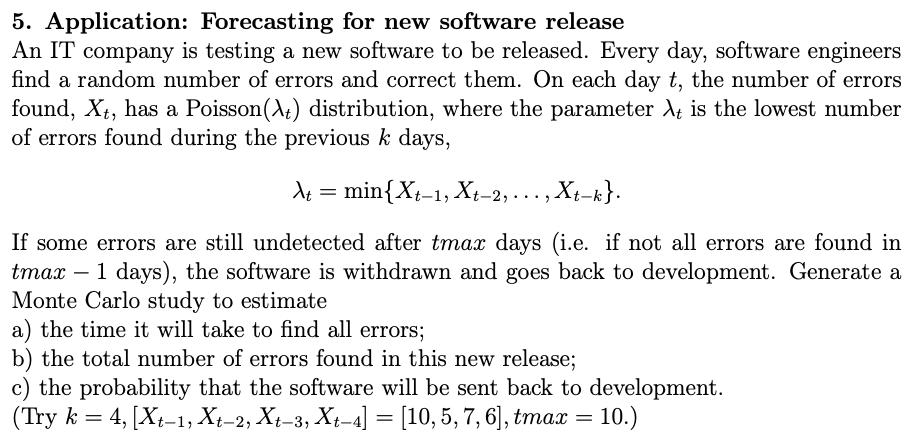

if generator==7
    N = computeSimulationsCount();

    k = input('number of previous days considered = ');
    in_last = input('number of errors in the last k days (vector of length k) = ');
        % initial number of errors in the last k days
    tmax = input('max time after which the new software is withdrawn (in days) = ');
    
    Ttotal = zeros(1, N); % Ttotal is the time it takes to find all the errors (in days)
    Ntotalerr = zeros(1, N); % Ntotalerr is the total number of errors that are detected
    
    for i=1:N
        % T is time from now on (in days), X is nr. of errors on day T
        % nrerr is the number of errors detected so far
    
        T = 0;
        last = in_last; % number of errors in the last k days
        X = in_last(k); % nr. of errors in day T
        nrerr = sum(in_last);
    
        while X > 0 % while loop until no errors are found
            lambda = min(last); % parameter for var X, Poisson (lambda)
            % Simulate the number of errors on day T, Poisson (lambda), special mehtod
            U = rand; % generated U(0,1) variable
            X = 0; % initial value
            while U >= exp(-lambda)
                U = U * rand;
                X = X + 1; % The Poisson variable
            end
    
            T = T + 1; % update: next day
            nrerr = nrerr + X; % update: new nr. of errors
            last = [last(2:k), X]; % update: new nrs of errors in the last k days
        end % the while loop ends when X = 0 on day T, that means that all errors were found on previous day, T - 1
    
        Ttotal(i) = T - 1; % the day all errors were found
        Ntotalerr(i) = nrerr; % total nr. of errors found
    end
    
    fprintf('a) The time it will take find all errors is %3.3f days', mean(Ttotal))
    fprintf('b) Total number of errors in the new release is %5.3f', mean(Ntotalerr))
    fprintf('c) Prob. that some errors will still be undetected errors after %d days', tmax)
    fprintf('after which the software will be withdrawn is %3.3f', mean(Ttotal > tmax))
end

Nr. of simulations N = 1138

a) The time it will take find all errors is 7.159 days

b) Total number of errors in the new release is 53.158

c) Prob. that some errors will still be undetected errors after 10 days

after which the software will be withdrawn is 0.192